**Statistical Methods**

**Luis Mario Bres Castro**

**Lab 5: Plot Frecuency Modulated Sinusoid Signal **

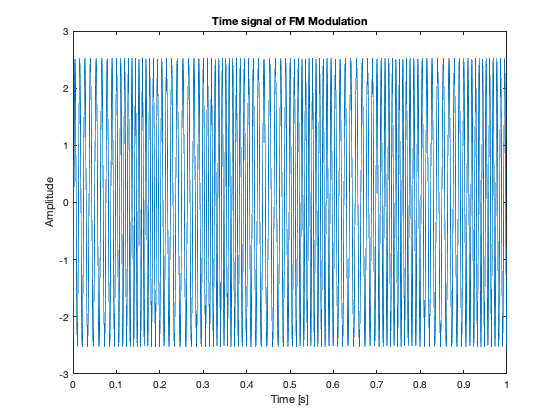

pmlibRootDir = '/Users/luisbres/Desktop/Spring 2022/StatisticalMethods';
addpath(genpath(pmlibRootDir),"-begin");

%Signal Parameters
A=100; 
b=5;
f0=100;
f1=5;
psi=0;

%Instantaneous phase
%I(t)=2*pi*f0*t+b*cos(2*pi*f0*t)
%dI/dt=2*pi*f0-2*pi*f0*b*sin(2*pi*f0*t)
%f(1)=2*pi*f0(1-b*sin(2*pi*f0))

%Time samples 
maxFreq=2*pi*f0*(1-b*sin(2*pi*f0));
samplFreq = 5*maxFreq;
samplIntrvl = 1/samplFreq;
t=0:samplIntrvl:1;
% Number of samples
nSamples = length(t);
%Generate Signal
SigVec = FMSigGen(t,A,b,f0,f1,psi);
plot(t,SigVec)
title('Time signal of FM Modulation')
xlabel('Time [s]')
ylabel('Amplitude')

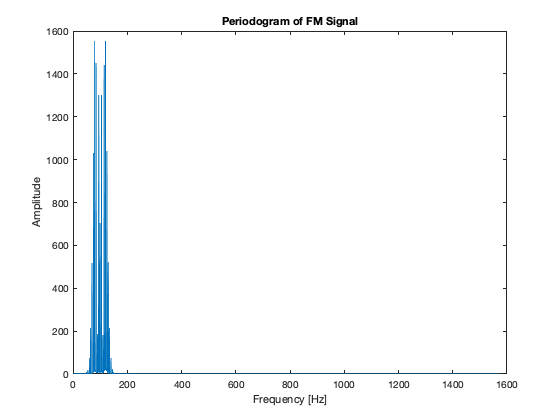

%Plot the periodogram

%Length of data 
dataLen = t(end)-t(1);
%DFT sample corresponding to Nyquist frequency
kNyq = floor(nSamples/2)+1;
% Positive Fourier frequencies
posFreq = (0:(kNyq-1))*(1/dataLen);
% FFT of signal
fftSig = fft(SigVec);
% Discard negative frequencies
fftSig = fftSig(1:kNyq);

%Plot periodogram
figure;
plot(posFreq,abs(fftSig));
title('Periodogram of FM Signal')
xlabel('Frequency [Hz]')
ylabel('Amplitude')

%Digital Filtering

sFreq = 1024; %sampling frequency
mFreq=sFreq/2; %maximum frequency
nS = 2048; %number of samples
td = (0:(nS-1))/sFreq;
f1=1;
b=5;

%Signal 1
A1=10;
f0_1=100;
psi0_1=0;
s1 = FMSigGen(td,A1,b,f0_1,f1,psi0_1);
%Signal 1
A2=5;
f0_2=200;
psi0_2=pi/6;
s2 = FMSigGen(td,A2,b,f0_2,f1,psi0_2);

%Signal 3
A3=2.5;
f0_3=300;
psi0_3=pi/4;
s3 = FMSigGen(td,A3,b,f0_3,f1,psi0_3);

%Superposed Signal
S=s1+s2+s3;

%Length of data 
dl = td(end)-td(1);
%DFT sample corresponding to Nyquist frequency
kNyq1 = floor(nS/2)+1;
% Positive Fourier frequencies
posFreq = (0:(kNyq1-1))*(1/dl);
% FFT of signal
fft_S = fft(S);
% Discard negative frequencies
fft_S = fft_S(1:kNyq1);

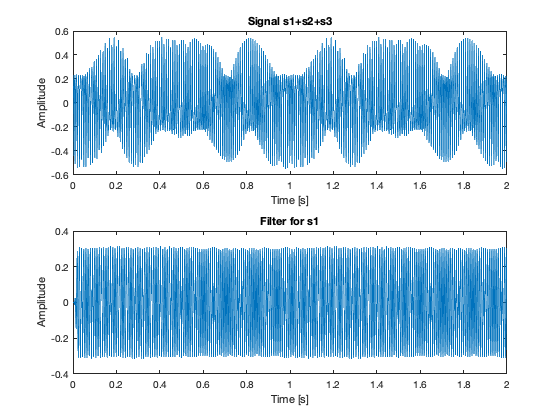

% Low pass filter for s1
filtOrdr = 30;
b1 = fir1(filtOrdr,(150)/(sFreq/2));
% Apply filter
filtS1 = fftfilt(b1,S);

%Plot of signal S and signal filtered S1 on the time domain
figure
subplot(2,1,1)
plot(td,S)
title('Signal s1+s2+s3')
xlabel('Time [s]')
ylabel('Amplitude')
subplot(2,1,2)
plot(td,filtS1)
title('Filter for s1')
xlabel('Time [s]')
ylabel('Amplitude')

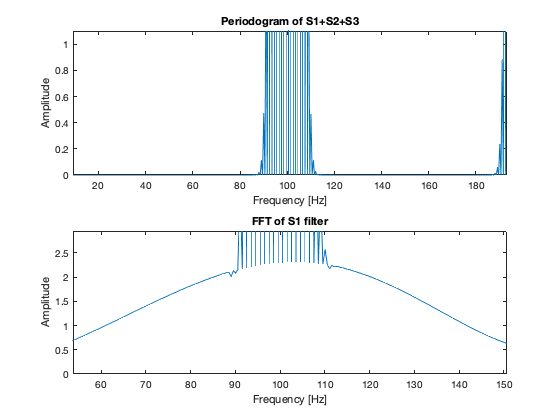


%Plot of signal S and signal filtered S1 on the frequency domain
figure
subplot(2,1,1)
plot(posFreq,abs(fft_S));
title('Periodogram of S1+S2+S3')
xlabel('Frequency [Hz]')
ylabel('Amplitude')
subplot(2,1,2)
% FFT of signal
fft_S1 = fft(filtS1);
% Discard negative frequencies
fft_S1 = abs(fft_S1(1:kNyq1));
plot(posFreq,fft_S1)
title('FFT of S1 filter')
xlabel('Frequency [Hz]')
ylabel('Amplitude')

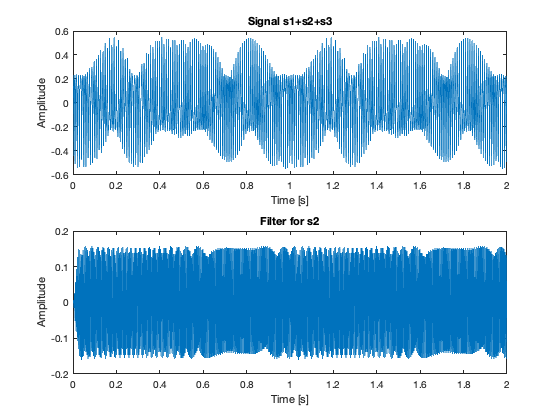

%Low pass filter for s2
filtOrdr = 30;
b2= fir1(filtOrdr,[(180)/(sFreq/2) (220)/(sFreq/2)]);
% Apply filter
filtS2 = fftfilt(b2,S);

%Plot of signal S and signal filtered S2 on the time domain
figure
subplot(2,1,1)
plot(td,S)
title('Signal s1+s2+s3')
xlabel('Time [s]')
ylabel('Amplitude')
subplot(2,1,2)
plot(td,filtS2)
title('Filter for s2')
xlabel('Time [s]')
ylabel('Amplitude')

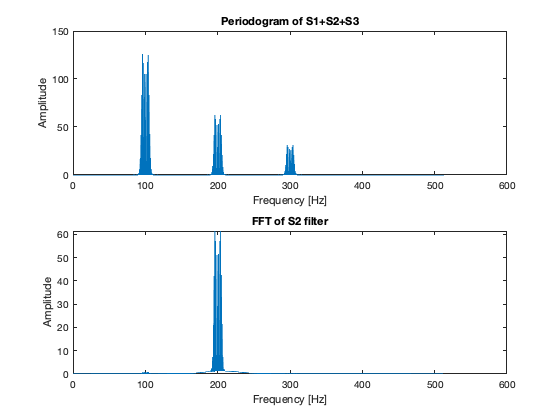


%Plot of signal S and signal filtered S2 on the frequency domain
figure
subplot(2,1,1)
plot(posFreq,abs(fft_S));
title('Periodogram of S1+S2+S3')
xlabel('Frequency [Hz]')
ylabel('Amplitude')
subplot(2,1,2)
% FFT of signal
fft_S2= fft(filtS2);
% Discard negative frequencies
fft_S2 = abs(fft_S2(1:kNyq1));
plot(posFreq,fft_S2)
title('FFT of S2 filter')
xlabel('Frequency [Hz]')
ylabel('Amplitude')

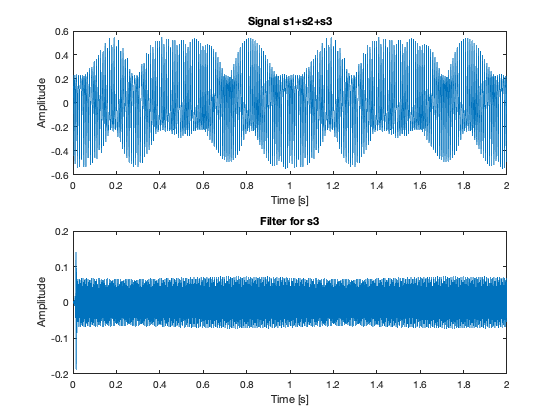

%Low pass filter for s3
filtOrdr = 30;
b3= fir1(filtOrdr,(270)/(sFreq/2),'high');
% Apply filter
filtS3 = fftfilt(b3,S);

%Plot of signal S and signal filtered S3 on the time domain
figure
subplot(2,1,1)
plot(td,S)
title('Signal s1+s2+s3')
xlabel('Time [s]')
ylabel('Amplitude')
subplot(2,1,2)
plot(td,filtS3)
title('Filter for s3')
xlabel('Time [s]')
ylabel('Amplitude')

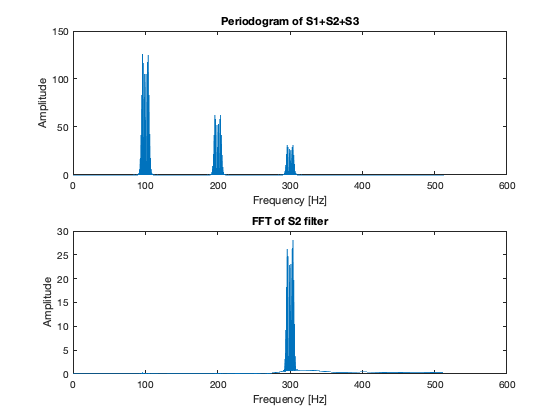




%Plot of signal S and signal filtered S1 on the frequency domain
figure
subplot(2,1,1)
plot(posFreq,abs(fft_S));
title('Periodogram of S1+S2+S3')
xlabel('Frequency [Hz]')
ylabel('Amplitude')
subplot(2,1,2)
fft_S3 = fft(filtS3);
% Discard negative frequencies
fft_S3 = abs(fft_S3(1:kNyq1));
plot(posFreq,fft_S3)
title('FFT of S2 filter')
xlabel('Frequency [Hz]')
ylabel('Amplitude')